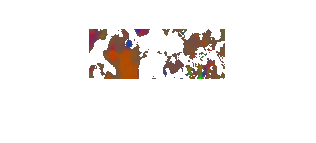

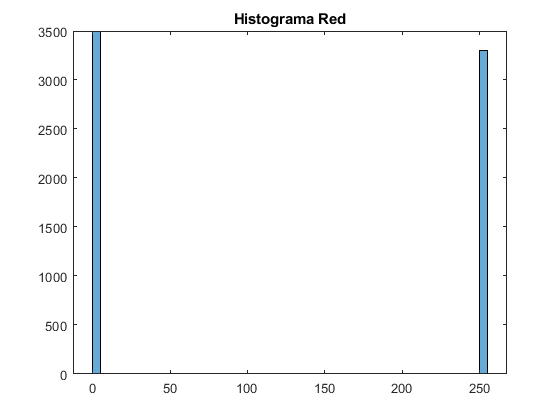

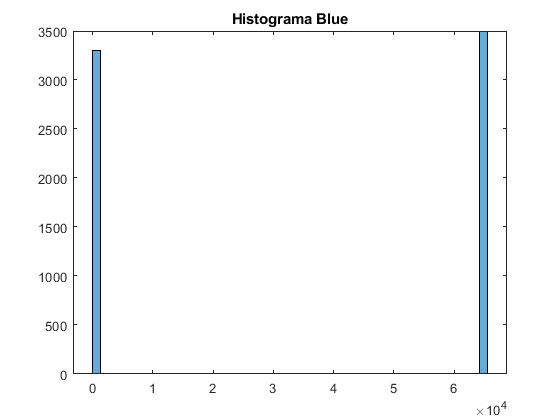

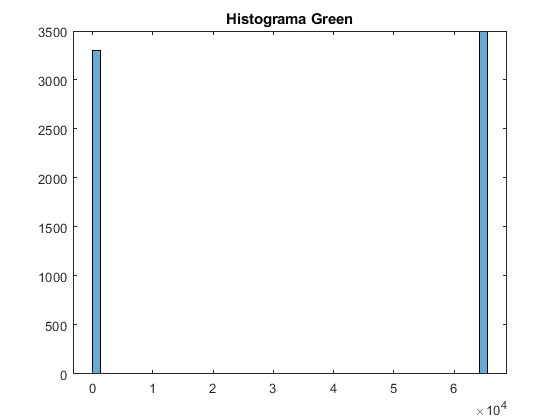

%UNTITLED Summary of this function goes here
%   Detailed explanation goes here
imageOG=imread('16.jpg');
image=double(imageOG);
%figure,imshow(uint8(image))

Image_red = image(:,:,1);
Image_green = image(:,:,2);
Image_blue = image(:,:,3);

[row,col] = size(image(:,:,1));

numBlocksVertical = 6;
numBlocksHoritzonal = 3;
totalBlocks = numBlocksHoritzonal*numBlocksVertical;
rowSize = uint32(row/numBlocksVertical) - 1;
colSize = uint32(col/numBlocksHoritzonal) - 1;
pixelsBlock = rowSize * colSize;

endrow = uint32(row*8);
endcol = uint32(col*5);

isBarsaImatge = 0;
moltGris = 0;
isBarsaBlock = 1;
blocksBarsa = 0;
maxRedLeft = 7;
maxRedRight = 31;
maxBlueLeft = 11;
maxBlueRight = 29;

vectorGreen = zeros(50);
vectorBlue = zeros(50);
vectorRed = zeros([52 1]);

for i = 1:numBlocksHoritzonal
    for j = 1:numBlocksVertical
        startrow = j*rowSize - rowSize + 1;
        startcol = i*colSize - colSize + 1;
        endrow = startrow + rowSize;
        endcol = startcol + colSize;
        
        if (i == numBlocksHoritzonal)
            endcol = col;
        end
        if (j == numBlocksVertical)
            endrow = row;
        end
        
        vectorRed = zeros([52 1]);
        vectorGreen = zeros([52 1]);
        vectorBlue = zeros([52 1]);
        isBarsaBlock = 1;
        moltGris = 0;
        
        for y = startrow:endrow 
            for x = startcol:endcol 
              Red = Image_red(y,x);
              Green = Image_green(y,x);
              Blue = Image_blue(y,x);
     
              NormalizedRed = Red/(Red + Green + Blue);
              NormalizedGreen = Green/(Red + Green + Blue);
              NormalizedBlue = Blue/(Red + Green + Blue);  
            
              Image_red(y,x) = NormalizedRed;
              Image_green(y,x) = NormalizedGreen;
              Image_blue(y,x) = NormalizedBlue;
              
              NormalizedRed = NormalizedRed*255;
              NormalizedGreen = NormalizedGreen*255;
              NormalizedBlue = NormalizedBlue*255;
              
              if (abs(NormalizedRed - NormalizedGreen) < 25)
                  if (abs(NormalizedBlue - NormalizedGreen) < 25)
                      Image_red(y,x) = 1;
                      Image_green(y,x) = 1;
                      Image_blue(y,x) = 1;

                      NormalizedRed = 255;
                      NormalizedGreen = 255;
                      NormalizedBlue = 255;
                  end
              end
              
              indexRed = uint8(NormalizedRed/5);
              indexRed = indexRed + 1;
              vectorRed(indexRed) = vectorRed(indexRed) + 1;
              
              indexBlue = uint8(NormalizedBlue/5);
              indexBlue = indexBlue + 1;
              vectorBlue(indexBlue) = vectorRed(indexBlue) + 1;
              
              indexGreen = uint8(NormalizedGreen/5);
              indexGreen = indexGreen + 1;
              vectorGreen(indexGreen) = vectorGreen(indexGreen) + 1;
              
              
            end
        end
        
        [maxElementRed, maxIndexRed] = max(vectorRed(1:end-1));
        [maxElementGreen, maxIndexGreen] = max(vectorGreen(1:end-1));
        [maxElementBlue, maxIndexBlue] = max(vectorBlue(1:end-1));
        
        if (abs(maxIndexBlue - maxIndexRed) < 2)
          if (abs(maxIndexBlue - maxIndexGreen) < 2)
              moltGris = 0;
          end
        end
        
        if (moltGris == 0)
            vectorBlueLeft = vectorBlue(1:26);
            vectorBlueRight = vectorBlue(27:end-1);
            
            vectorRedLeft = vectorRed(1:26);
            vectorRedRight = vectorRed(27:end-1);
            
            [maxElementRedLeft, maxIndexRedLeft] = max(vectorRedLeft);
            [maxElementRedRight, maxIndexRedRight] = max(vectorRedRight);
            
            [maxElementBlueLeft, maxIndexBlueLeft] = max(vectorBlueLeft);
            [maxElementBlueRight, maxIndexBlueRight] = max(vectorBlueRight);
            
            maxIndexBlueRight = maxIndexBlueRight + 26;
            maxIndexRedRight = maxIndexRedRight + 26;
            
            tolerance = 6;
            threshold = 100;
            if (maxElementBlueLeft > threshold && maxElementBlueRight > threshold)
                if (maxElementRedLeft > threshold && maxElementRedRight > threshold)
                    if (abs(maxBlueLeft - maxIndexBlueLeft) < tolerance)
                       if (abs(maxRedLeft - maxIndexRedLeft) < tolerance)
                           if (abs(maxBlueRight - maxIndexBlueRight) < tolerance)
                               if (abs(maxRedRight - maxIndexRedRight) < tolerance)
                                   blocksBarsa = blocksBarsa + 1
                               end
                           end
                       end
                    end
                end
            end
%         else
%             vectorBlueLeft = vectorBlue(1:26);
%             vectorBlueRight = vectorBlue(27:end);
%             
%             vectorRedLeft = vectorRed(1:26);
%             vectorRedRight = vectorRed(27:end);
%             
%             [maxim, maxIndexRedLeft] = max(vectorRedLeft);
%             [maxim, maxIndexRedRight] = max(vectorRedRight);
%             
%             [maxim, maxIndexBlueLeft] = max(vectorBlueLeft);
%             [maxim, maxIndexBlueRight] = max(vectorBlueRight);
%             
%             maxIndexBlueRight = maxIndexBlueRight + 26;
%             maxIndexRedRight = maxIndexRedRight + 26;
%             tolerance = 5;
%             if (abs(maxBlueLeft - maxIndexBlueLeft) < tolerance)
%                if (abs(maxRedLeft - maxIndexRedLeft) < tolerance)
%                    if (abs(maxBlueRight - maxIndexBlueRight) < tolerance)
%                        if (abs(maxRedRight - maxIndexRedRight) < tolerance)
%                            blocksBarsa = blocksBarsa + 1
%                        end
%                    end
%                end
%             end
        end
        
% %         Descomentar per veure com genera els blocks
         image(:,:,1) = Image_red;
         image(:,:,2) = Image_green;
         image(:,:,3) = Image_blue;
         
         
        figure; imshow(uint8(255*image(startrow:endrow,startcol:endcol,:)));
            
         figure; histogram(Image_red_hist(startrow:endrow,startcol:endcol)*255, 50), title('Histograma Red')
         figure; histogram(Image_blue(startrow:endrow,startcol:endcol)*255, 50), title('Histograma Blue')
         figure; histogram(Image_green(startrow:endrow,startcol:endcol)*255, 50), title('Histograma Green')
     end
end



if (blocksBarsa/totalBlocks > 0.25) 
    isBarsaImatge = 1;
end

image(:,:,1) = Image_red;
image(:,:,2) = Image_green;
image(:,:,3) = Image_blue;


 figure; imshow(uint8(255*image));
% 
% % histogram(image, nBins)
% histogram(Image_red(:,:)*255, 50), title('Histograma Red')
% histogram(Image_blue(:,:)*255, 50), title('Histograma Blue')
% histogram(Image_green(:,:)*255, 50), title('Histograma Green')


outputArg1 = blocksBarsa;

